
clc, clearvars

# **MRI local wire simulation**

The purpose of wire_function() is to simulate the path of a local wire through the body in the electric field.  

## **Required Inputs**

eField (as a file name):

"simulatedBodyCoilEfield (1).mat"

ans = "simulatedBodyCoilEfield (1).mat"

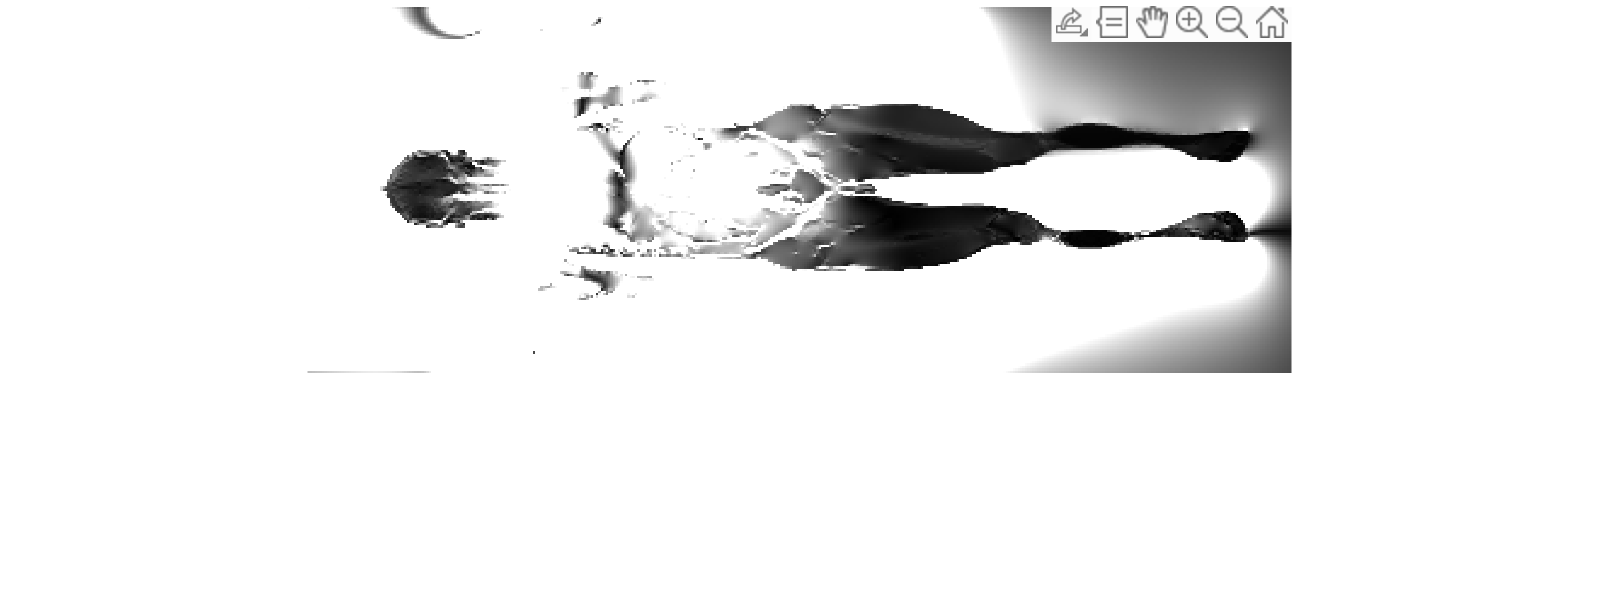

z =    93.7568
  144.0902
  181.2213
  357.8005


x =    77.4440
   65.0669
   83.2199
   23.8101


s = load(ans);
title('Saggital')
imshow(squeeze(abs(s.E(:,75,:,1))))
set(gcf,'Position',[300 300 800 300])
[z, x] = getpts

Pick your points for the y direction on the green lines. 

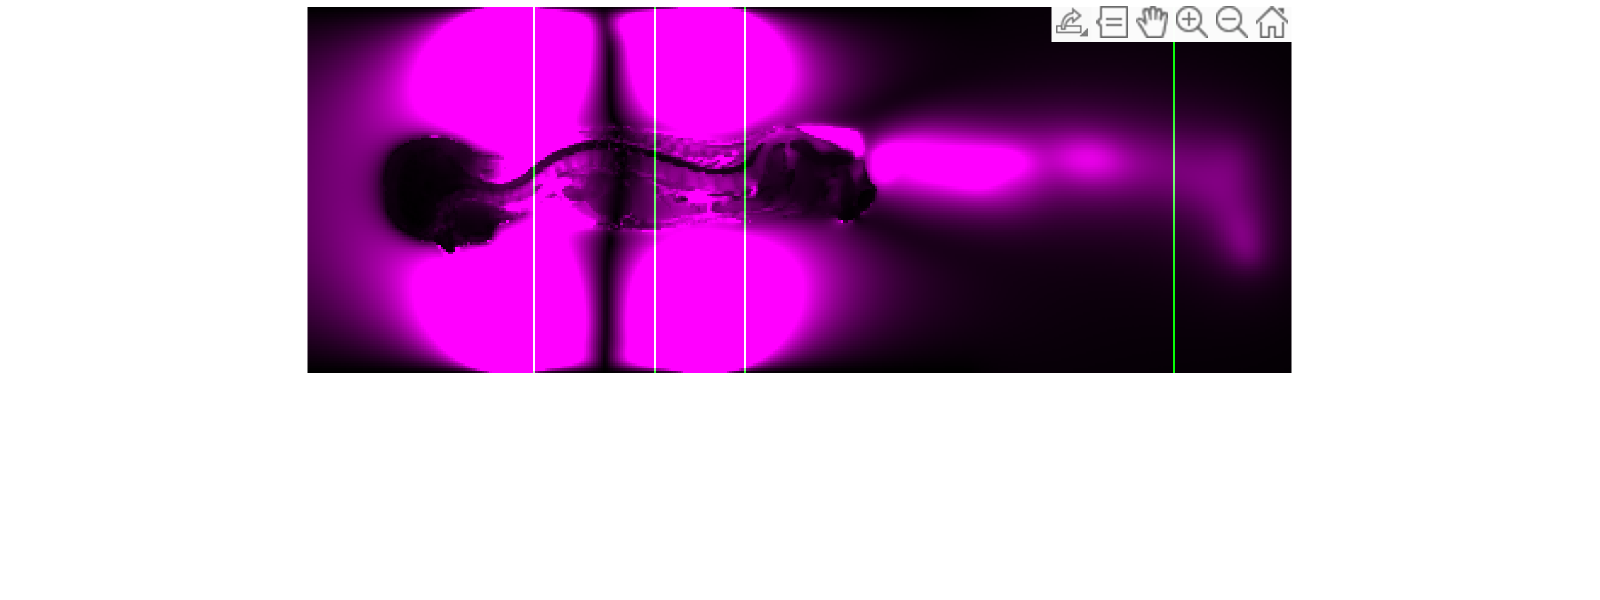


vol = zeros(length(s.axis1)-1, length(s.axis2)-1);
vol(:,round(z)) = 1;

s.E(abs(s.E) > 5) = 5;
imshow(imfuse(vol, squeeze(abs(s.E(75,:,:,1)) ), 'Scaling', 'independent')) 
set(gcf,'Position',[300 300 800 300])
[zc, y] = getpts;

p = [x, y, z];
points = convert_points(p, s, 'version', "v1")

output =      1     1     1
     1     1     1
     1     1     1
     1     1     1


points =     0.0033   -0.0417   -0.1542
   -0.0567   -0.0267    0.0958
    0.0333   -0.0417    0.2808
   -0.2617   -0.2667    1.1658


num_points = size(points, 1);     

Pick the minimum and maximum values for each of your points. 

1) Select a value above and below for the x direction.

2) Select a value to the right and left when choosing z ranges. 

3) Select a value above and below for the y direction. 

Coordinates that you do not specify as changing later on will not be used. **Pick maximum first and minimum second for each point. **

y ranges:

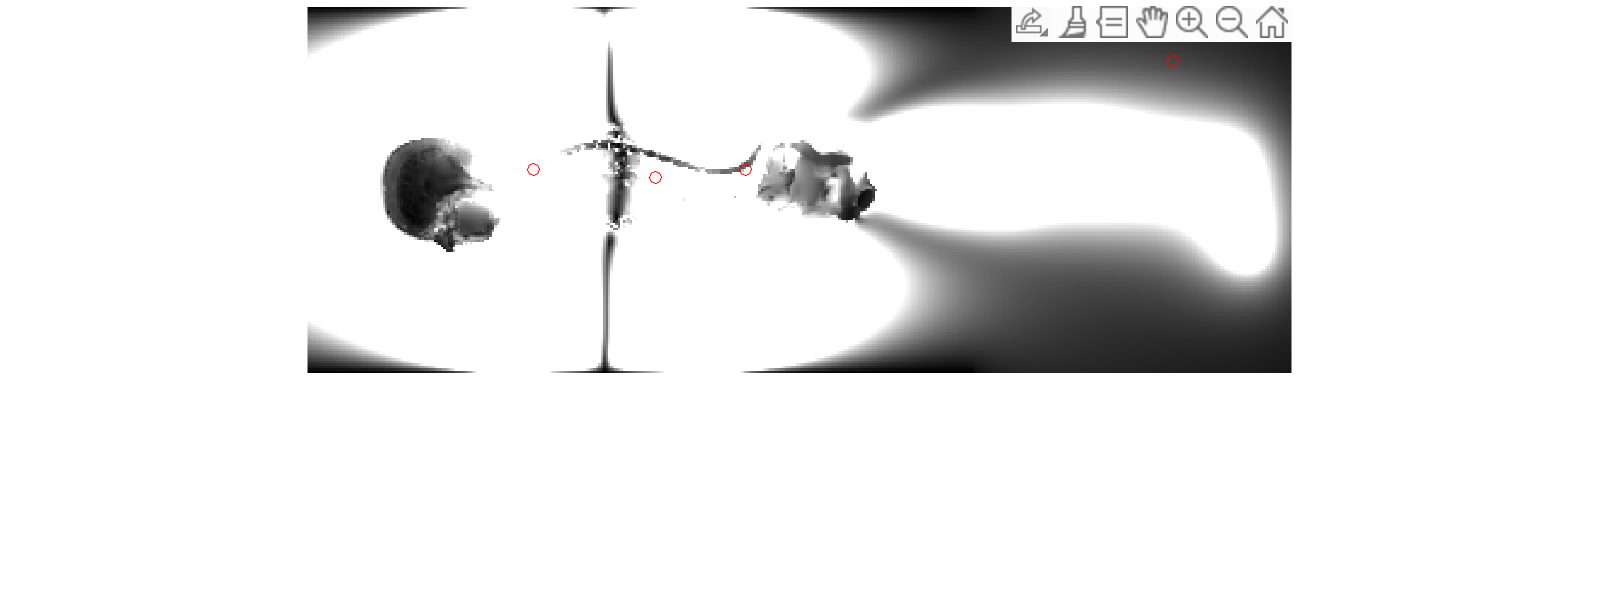

zn =    97.0574
   97.0574
  146.5656
  146.5656
  183.6967
  184.5219
  360.2760
  360.2760


y_ranges =    63.4167
   72.4932
   59.2910
   78.2691
   58.4658
   74.1434
   20.5096
   29.5861


%voll = zeros(length(s.axis1)-1, length(s.axis2)-1);
%voll(round(points()),round(points(:, 1:2))) = 1; %how to only do points?
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[zn, y_ranges] = getpts

y_ranges = reshape(y_ranges, 2, num_points)' %check if order is correct

y_ranges =    63.4167   72.4932
   59.2910   78.2691
   58.4658   74.1434
   20.5096   29.5861


y_ranges = convert_points(y_ranges, s, 'version', "v2", 'yd', "T")

y_ranges =    -0.0667   -0.0217
   -0.0867    0.0083
   -0.0917   -0.0117
   -0.2767   -0.2317


z ranges:

z_ranges =    80.5546
  104.4836
  132.5383
  153.1667
  171.3197
  188.6475
  349.5492
  369.3525


yn =    68.3675
   67.5423
   71.6680
   71.6680
   66.7172
   66.7172
   22.9850
   22.9850


%same plot
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[z_ranges, yn] = getpts

z_ranges = reshape(z_ranges, 2, num_points)'%convert points

z_ranges =    80.5546  104.4836
  132.5383  153.1667
  171.3197  188.6475
  349.5492  369.3525


z_ranges = convert_points(z_ranges, s, 'version', "v2", 'zd', "T")

z_ranges =    -0.2192   -0.1042
    0.0408    0.1408
    0.2308    0.3208
    1.1258    1.2208


x ranges:

imshow(squeeze(abs(s.E(:,75,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, x, 'ro');
hold off
[zn, x_ranges] = getpts

zn =    94.5820
   94.5820
  143.2650
  144.0902
  180.3962
  182.0464
  359.4508
  359.4508


x_ranges =    63.4167
   88.9959
   53.5150
   89.8210
   64.2418
   98.8975
   18.8593
   34.5369


x_ranges = reshape(x_ranges, 2, num_points)'

x_ranges =    63.4167   88.9959
   53.5150   89.8210
   64.2418   98.8975
   18.8593   34.5369


%x_ranges = reshape(x_ranges, 2, [])'
x_ranges = convert_points(x_ranges, s, 'version', "v2", 'xd', "T")

x_ranges =    -0.0667    0.0633
   -0.1117    0.0683
   -0.0617    0.1133
   -0.2867   -0.2067


ranges = [x_ranges y_ranges z_ranges];

which points will be changing (give a list of their indices): 

[1 2 3]

ans =      1     2     3


check of all of the points that are changing:

changing = ans;

## **Optional Inputs**

Drag to choose how long you want your wire to be. Your points will be adjusted to this length. Units are in meters. 

1

ans = 1

nom_length = ans;

Do you want a plot of the wire to be displayed?

"Yes"

ans = "Yes"

if ans == "Yes"
    show_plot = true;
else
    show_plot = false;
end

Do you want a histogram of the lengths of the trajectories for the wire (modified and unmodified) to be displayed?

"Yes"

ans = "Yes"

if ans == 'Yes'
    show_graph = true;
else
    show_graph = false;
end

What is the indice of the point on the wire that intersects with the body?

3

ans = 3

intersecting = ans;

Drag to pick the number of steps between ranges. For example, if there is a range [-1 2] and num_steps is 3, the function will use 3 values in between -1  and 2. Default value: 5. num_steps^3 is the number of trajectories that will be calculated. 

5

ans = 5

num_steps = ans;
set(gcf,'Position',[300 300 700 700]) %weird transition

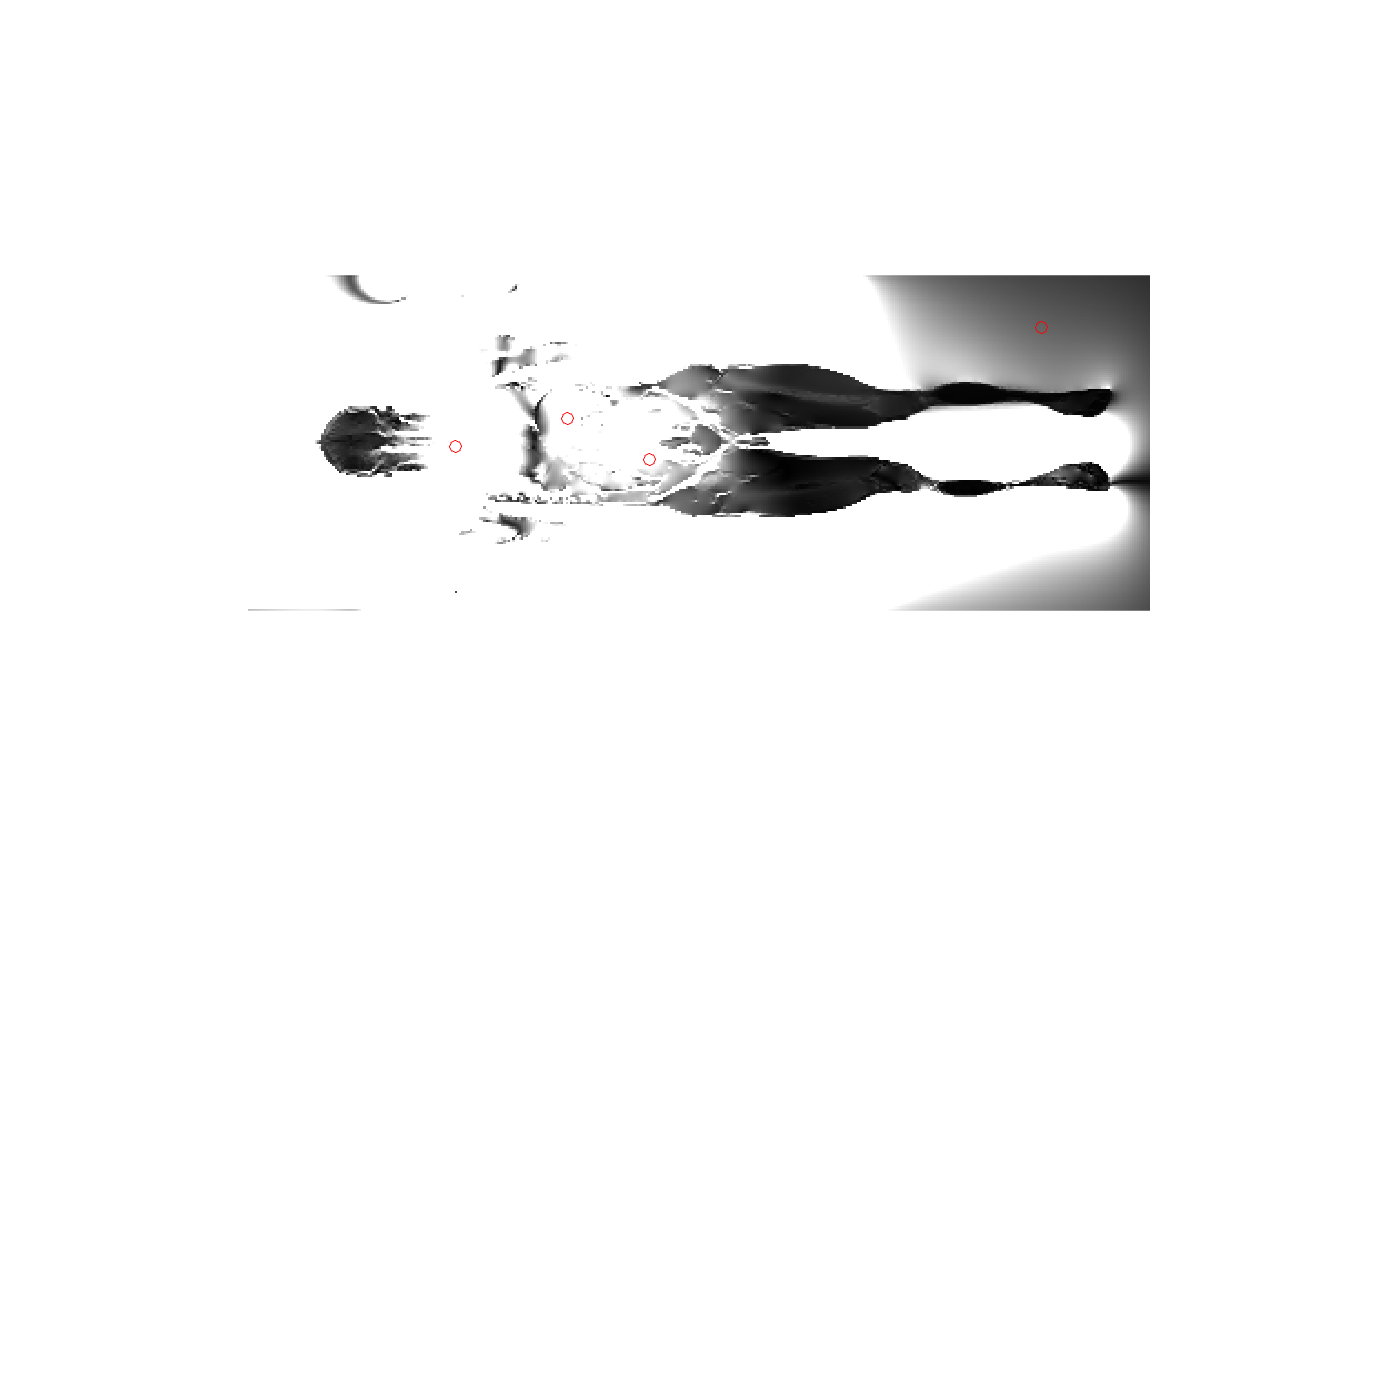

show_electric = logical
   1


length of rounded wire 1.01

length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00l

length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.01length of rounded wire 1.00length of rounded wire 1.02length of rounded wire 1.01length of rounded wire 1.01length of rounded wire 1.00l

length of rounded wire 1.10length of rounded wire 1.09

length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.11length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.11length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.09length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.10length of rounded wire 1.09l

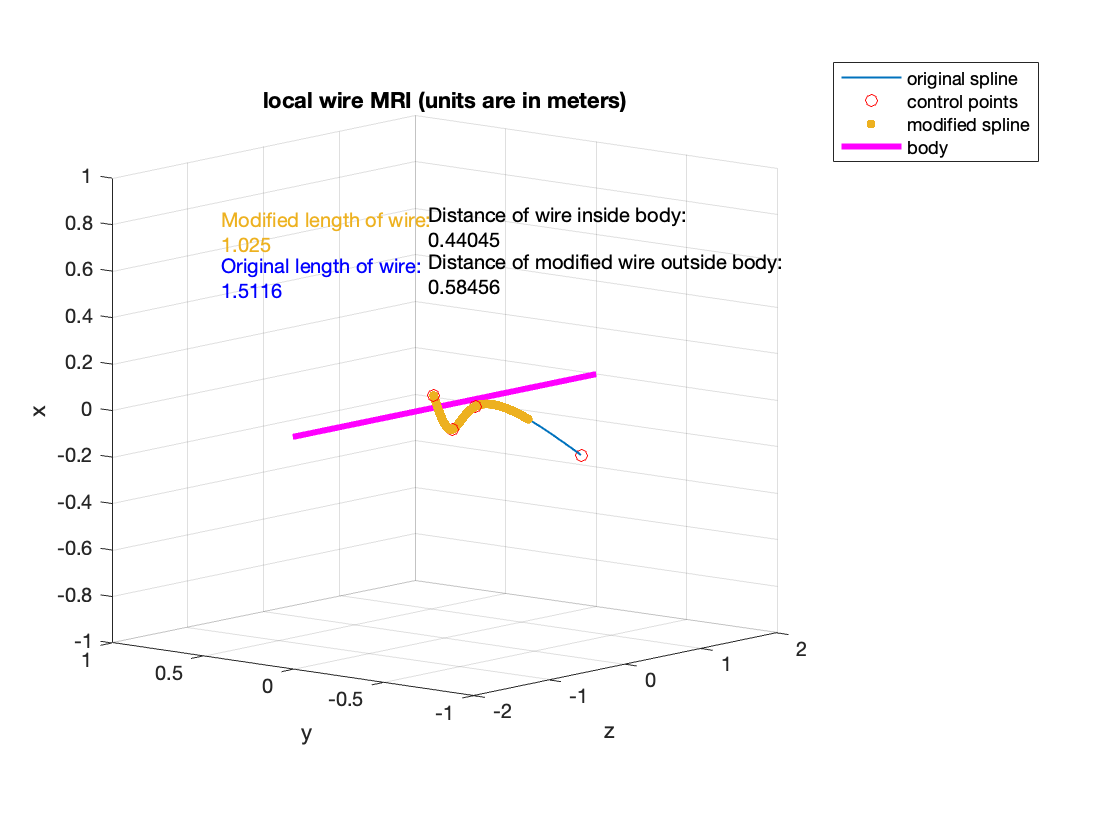

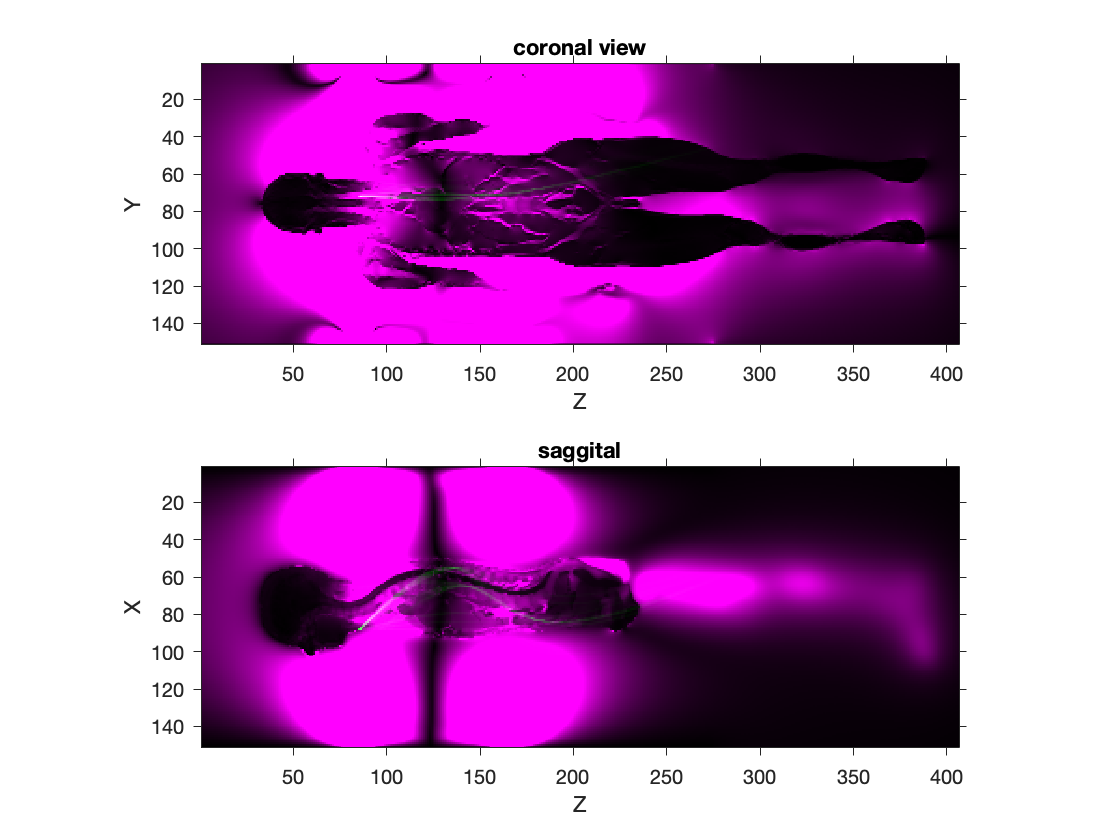

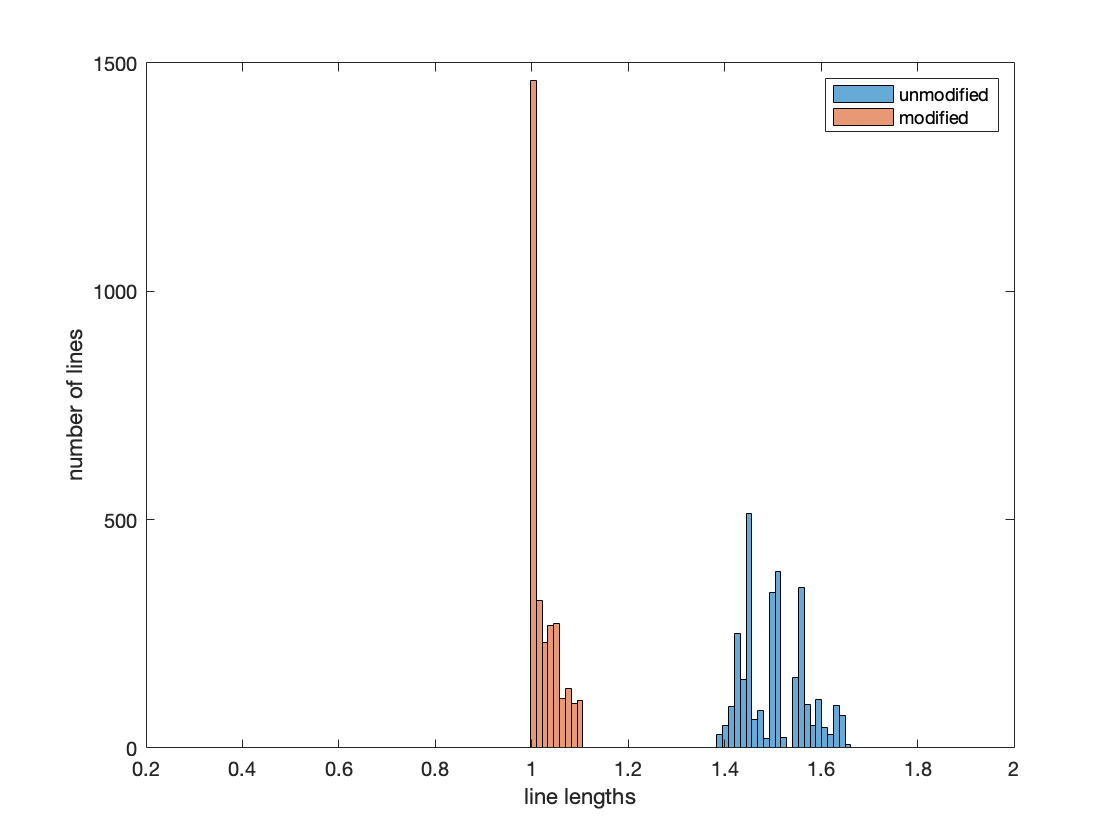

graph_creation2(...
    points',...
    ranges,...
    changing,...
    s,...
    'nom_length', nom_length,...
    'show_plot', show_plot,...
    'show_graph', show_graph,...
    'intersecting_index', intersecting,...
    'num_steps', 10,... %changed from num_steps
    'give_warnings', false, ... 
    'direction', "Right");